function [x,y, A] = locate_point_source_2d(sensorPos, I)
% LOCATE_POINT_SOURCE_2D Estimate 2D point-source position and strength.
%   sensorPos: N x 2 matrix of sensor coordinates [x_i y_i]
%   I        : N x 1 vector of measured intensities (positive)
% Returns:
%   p = [x y] (1x2)
%   A = scalar strength, I_i ≈ A / ||p - s_i||^2
%
% Requires N >= 3. If N > 3 solves in least-squares sense.

    sensorPos = double(sensorPos);
    I = double(I(:));
    N = size(sensorPos,1);

    if size(sensorPos,2) ~= 2
        error('sensorPos must be N×2');
    end
    if N < 3
        error('Need at least 3 sensors');
    end
    if any(I <= 0)
        error('All intensities must be positive for 1/r^2 model');
    end

    s1 = sensorPos(1,:);
    I1 = I(1);

    % Build linear system M * p = b using sensors 2..N
    M = zeros(N-1, 2);
    b = zeros(N-1, 1);
    for k = 2:N
        si = sensorPos(k,:);
        Ii = I(k);
        M(k-1, :) = 2*(I1*s1 - Ii*si);                 % 1x2
        b(k-1)    = I1*(s1*s1') - Ii*(si*si');         % scalar
    end

    % Solve (least squares if overdetermined)
    p_vec = M \ b;   % 2x1
    p = reshape(p_vec, 1, 2);
    x=p(1);
    y=p(2);

    % Compute A by averaging A_i = I_i * r_i^2
    r2 = sum((sensorPos - p).^2, 2);   % Nx1
    if any(r2 == 0)
        error('Solution places source exactly at a sensor location (r=0)');
    end
    Avals = I .* r2;
    A = mean(Avals);

end



sensorPos = [m_1; m_2; m_3; m_4];

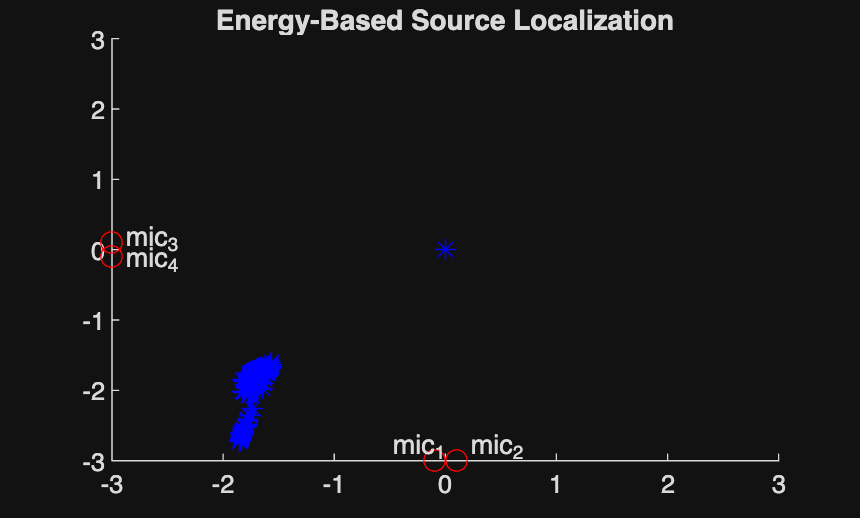

cmap = jet(length(nbcoupe));    % or jet(n), hsv(n), etc. parula

clf


figure();
hold on;
xlim([-3 3]); ylim([-3 3]);
title('Energy-Based Source Localization');

% Plot Microphones
plot(m_1(1),m_1(2),'ro','MarkerSize',8)
text(m_1(1) - 0.4, m_1(2) + 0.2, 'mic_1')
plot(m_2(1),m_2(2),'ro','MarkerSize',8)
text(m_2(1) + 0.1, m_2(2) + 0.2, 'mic_2')
plot(m_3(1),m_3(2),'ro','MarkerSize',8)
text(m_3(1) + 0.1, m_3(2) + 0.05, 'mic_3')
plot(m_4(1),m_4(2),'ro','MarkerSize',8)
text(m_4(1) + 0.1, m_4(2) - 0.05, 'mic_4')



trajectory = zeros(nbcoupe, 2);

% --- Main Processing Loop ---
for i = 1:nbcoupe
    % Extract sample indices for current scope
    idx = (i-1)*decalage + (1:nbpoint);
    
    %RMS calculation
    moy1 = rms(x1(idx));
    moy2 = rms(x2(idx));
    moy3 = rms(x3(idx));
    moy4 = rms(x4(idx));
    
    % Keeps intensities above small positive floor (e.g., 1e-6)
    eps_val = 1e-6; 
    intensities = max([moy1; moy2; moy3; moy4], eps_val);
    
    %Pass non-zero intensities to the localization solver
    [x, y, A] = locate_point_source_2d(sensorPos, intensities);    
    % Store position
    trajectory(i, :) = [x, y];
    

    plot(x, y, 'b*', 'MarkerSize', 8);
    drawnow limitrate; % Forces MATLAB to refresh the figure each iteration
end

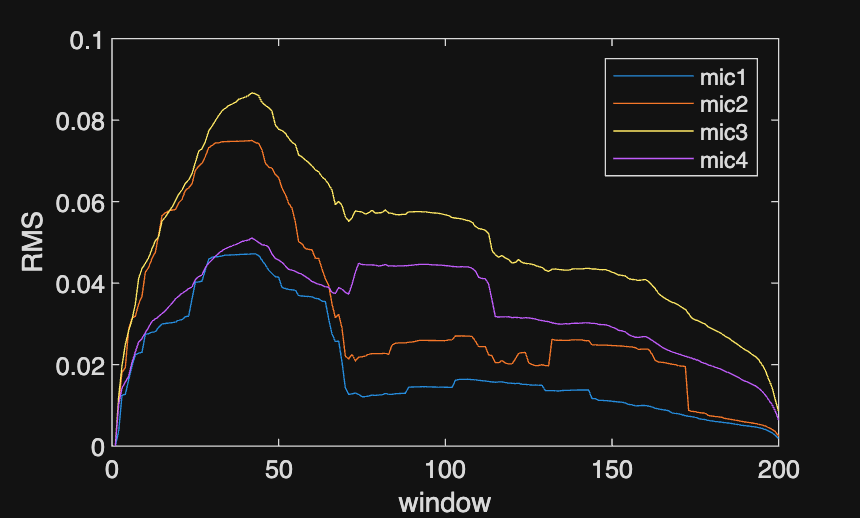


nbpoint = taillefenetre * fs;
decalage = floor((length(x1)-nbpoint)/nbcoupe);
Iall = zeros(nbcoupe, 4);

for i = 1:nbcoupe
    startIdx = (i-1)*decalage + 1;
    stopIdx = min(startIdx + nbpoint - 1, length(x1));
    seg1 = x1(startIdx:stopIdx);
    seg2 = x2(startIdx:stopIdx);
    seg3 = x3(startIdx:stopIdx);
    seg4 = x4(startIdx:stopIdx);
    Iall(i,1) = sqrt(mean(seg1.^2));   % RMS
    Iall(i,2) = sqrt(mean(seg2.^2));
    Iall(i,3) = sqrt(mean(seg3.^2));
    Iall(i,4) = sqrt(mean(seg4.^2));
end
figure; plot(Iall); legend('mic1','mic2','mic3','mic4'); xlabel('window'); ylabel('RMS');